clc; clearvars;

rng(0)

N_BINS=10;
CYCLES_PER_BIN=100;
l = N_BINS*CYCLES_PER_BIN;

pulse_train = NaN(l,1);

t = 30;

n = 1:l;
lam = n;

p = poissrnd(lam);
d = abs(p-lam);
photon_stream = d>t;

counts = NaN(N_BINS,1);

ids = ceilDiv(n,CYCLES_PER_BIN);
for i=1:N_BINS
    counts(i) = sum(photon_stream(ids==i));
end

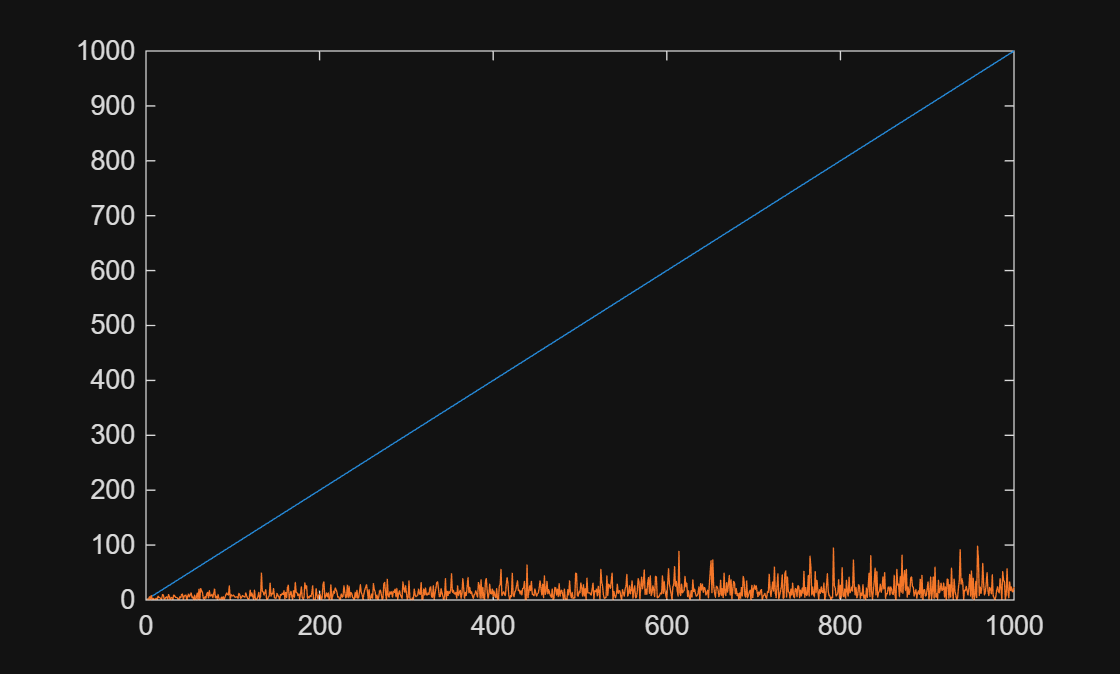

figure;
plot(n,lam);
hold on
plot(n,d)
yline(0)
hold off

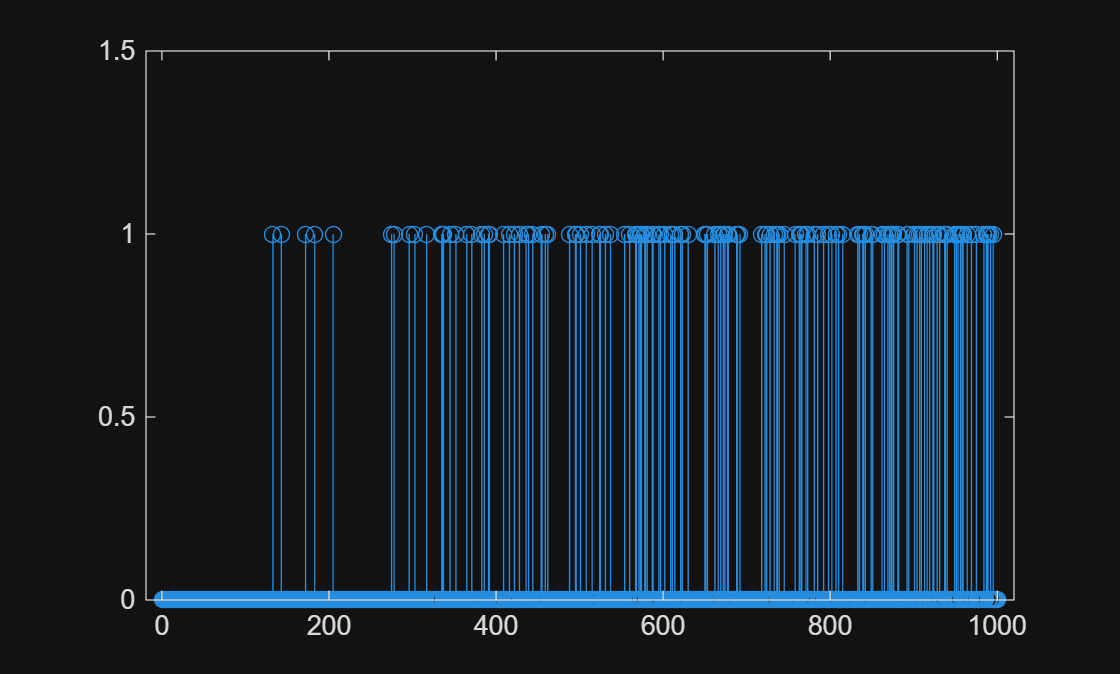

figure;
stem(n,photon_stream)
ylim([0 1.5])

writematrix(photon_stream',"photon_stream.dat");
writematrix(counts,"golden.dat");